## CNTtools Pipeline

This live script runs the full pipeline of the CNTtools.

## Set Paths & Params

The work path should be the folder containing the 'matlab' tools.

%set path
work_path = "/Users/meow/Downloads/UPenn/00_Thesis/script";
cd(work_path)
file_path = string(work_path)+'/matlab';
test_path = string(work_path)+'/matlab/test';

% Add path to this codebase
addpath(genpath('./..'))
assert(exist('IEEGToolbox','dir')==7,'CNTtools:dependencyUnavailable','IEEGToolbox not imported.')
assert(exist('tools','dir')==7,'CNTtools:dependencyUnavailable','Tools not imported.')

max_disp = 5; % need fix depending on different file

## Data Params

Accept type input or file upload. Two inputs will be combined together to run.

**File upload:** Input file should be of .csv format, with 5 columns, labeled as 

- **filename**: *string*, the name of target file at ieeg.org

- **start: ***numeric*, the start time of target clip in seconds 

- **stop: ***numeric*, the stop time of target clip in seconds 

- **out: ***string*, the expected situation of input params

- **notes: ***string*, name of test case, character and digit only

**Type input: **Input need to have exact sequence, split by comma ', '.

file_name = 'HUP212_phaseII';
begin_time = 100000;
end_time = 100015;
times = [begin_time end_time]; % maybe fetch file length first and have a range for time?
which_reference = 'bipolar';
[elec_names,elec_locs] = get_elec_names_locs_test(file_name);

%% Get patient name
ptnameC = strsplit(file_name,'_');
name = ptnameC{1}; 

Start Fetching...

%% Download data from ieeg.org
data = download_ieeg_data(file_name, login.usr, login.pwd, times, 1);
oldLabels = data.chLabels;
old_values = data.values;
fs = data.fs;
nchs = size(old_values,2);

Data information:

% for test
data
show_eeg(old_values,fs,oldLabels,max_disp);
set(gcf,'position',[0,0,500,500])
title('Sample Data')

## Pre-processing

### Decompose Labels

Channels after decompose:

%% Decompose labels
[labels,~,~] = decompose_labels(oldLabels,name);

% for test
comp_label_table=cell2table([setdiff(oldLabels(:,1),labels),setdiff(labels,oldLabels(:,1))], "VariableNames",["Before" "After"])

### Reconcile locs

Channel locs:

%% Reconcile locs and associated names with ieeg ch names
% This function takes elec_locs, corresponding 1:1 with elec_names, and
% returns locs, which corresponds 1:1 with labels.
locs = reconcile_ch_names(labels,elec_names,elec_locs,name); % can add plot
label_locs_table = cell2table([labels,num2cell(locs)],"VariableNames",["Electrode" "X","Y","Z"])

### Identify Non-intracranial Channels

IEEGSETUP: Adding 'ieeg-matlab.jar' to dynamic classpath
IEEGSETUP: Found log4j on Java classpath.
URL: https://www.ieeg.org/services
Client user: qaq233tvt
Client password: ****


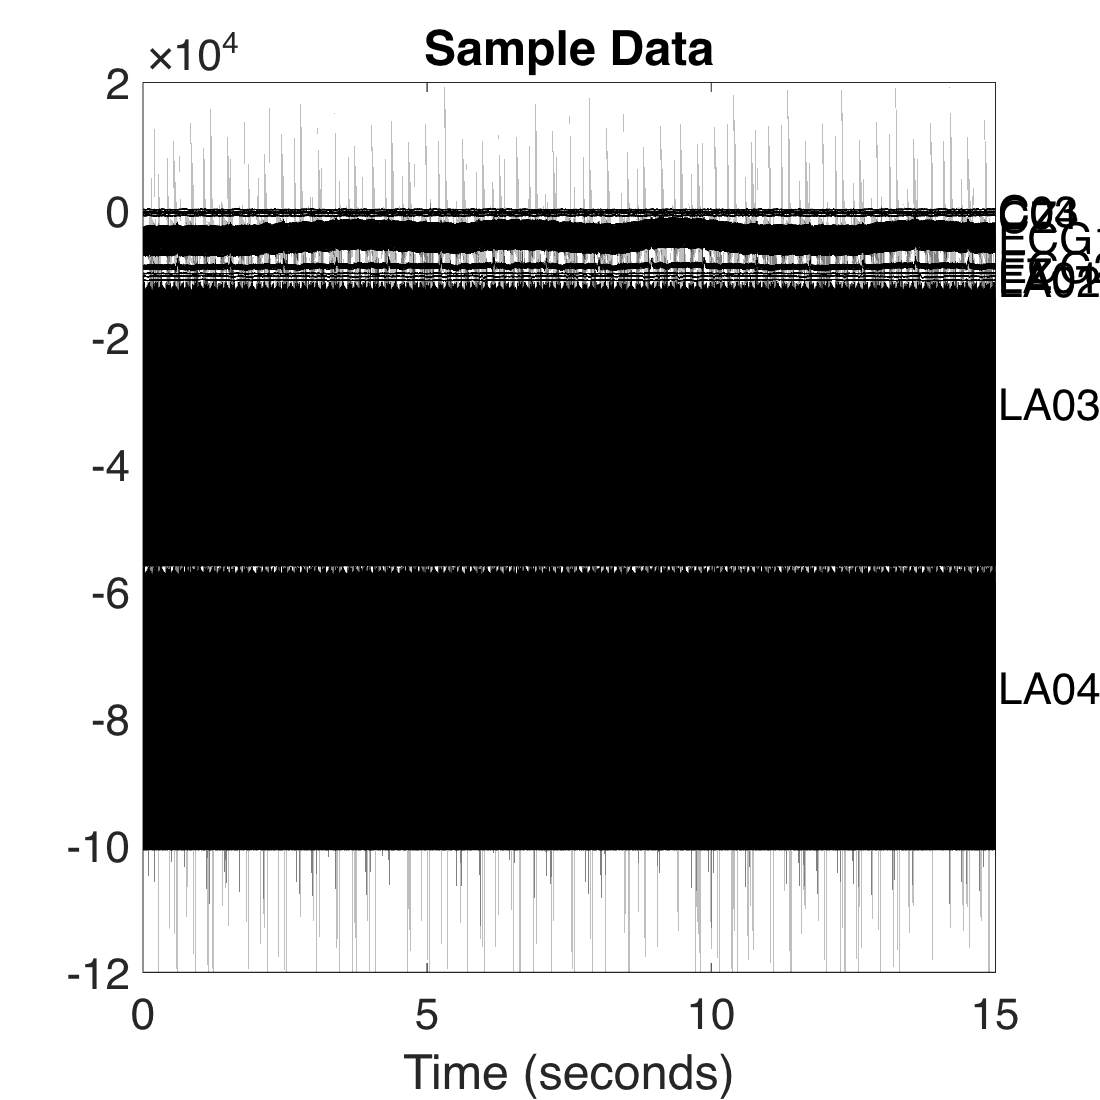

%% Non intracranial
extra_cranial = find_non_intracranial(labels);
% for test
extra_cranial_table = cell2table(labels(extra_cranial),"VariableNames",["Non-intracranial Channels"])

### Identify Bad Channels

%% Identify bad channels
bad = identify_bad_chs(old_values,fs);
%bad = logical(zeros(nchs,1)); % Uncomment this to see what happens if you
%don't remove bad channels!

% for test
bad_table = cell2table(labels(bad),"VariableNames",["Bad Channels"])
show_eeg(old_values(:,bad),fs,labels(bad),max_disp); % set display length?%maybe add a normal channel to adjust the scale
title('Sample bad channels')

comp_label_table = 89×2 table
     Before      After 
    ________    _______

    {'C03' }    {'C3' }
    {'C04' }    {'C4' }
    {'LA01'}    {'LA1'}
    {'LA02'}    {'LA2'}
    {'LA03'}    {'LA3'}
    {'LA04'}    {'LA4'}
    {'LA05'}    {'LA5'}
    {'LA06'}    {'LA6'}
    {'LA07'}    {'LA7'}
    {'LA09'}    {'LA9'}
    {'LB01'}    {'LB1'}
    {'LB02'}    {'LB2'}
    {'LB03'}    {'LB3'}
    {'LB04'}    {'LB4'}
    {'LB05'}    {'LB5'}
    {'LB06'}    {'LB6'}


%% Notch Filter
%old_values = notch_filter(old_values,fs);

### Re-reference

%% Common average reference (include only intra-cranial)
old_labels = labels;
switch which_reference
    case 'car'
        [values,labels] = common_average_reference(old_values,~extra_cranial&~bad,labels);
    case 'bipolar'

label_locs_table = 122×4 table
    Electrode       X            Y             Z      
    _________    ________    _________    ____________

    {'C3'  }          NaN          NaN             NaN
    {'C4'  }          NaN          NaN             NaN
    {'CZ'  }          NaN          NaN             NaN
    {'ECG1'}          NaN          NaN             NaN
    {'ECG2'}          NaN          NaN             NaN
    {'FZ'  }          NaN          NaN             NaN
    {'LA1' }     -21.9644     -3.96622    -19.17796222
    {'LA2' }     -27.1833     -3.44744    -18.44270233
    {'LA3' }     -32.3055     -3.15092    -17.79679578
    {'LA4' }     -39.0948     -1.25976    -16.59815643
    {'LA5' }     -44.0528    -0.489712    -15.40255739
    {'LA6' }     -48.5465     0.768958    -15.40850885
    {'LA7' }     -55.1978     0.807032    -15.15906381
    {'L

        [values,~,labels,chs_in_bipolar] = bipolar_montage(old_values,labels,[],[],name);
        bad_ref = any(ismember(chs_in_bipolar,find(bad)),2);
        extra_ref = any(ismember(chs_in_bipolar,find(extra_cranial)),2);
    case 'laplacian'
        radius = 50;
        [values,close_chs,labels] = laplacian_reference(...

extra_cranial_table = 8×1 table
    Non-intracranial Channels
    _________________________

            {'C3'  }         
            {'C4'  }         
            {'CZ'  }         
            {'ECG1'}         
            {'ECG2'}         
            {'FZ'  }         
            {'LOC' }         
            {'ROC' }         


            old_values,~extra_cranial&~bad,locs,radius,labels);        
end

% for test
show_eeg(values,fs,labels,max_disp);
title('Sample Re-reference Data')

### Remove Bad Channels

%% Remove bad channels
switch which_reference
    case 'car'

bad_table = 37×1 table
    Bad Channels
    ____________

      {'C3'  }  
      {'ECG1'}  
      {'LA3' }  
      {'LA4' }  
      {'LA5' }  
      {'LA6' }  
      {'LA7' }  
      {'LA9' }  
      {'LA10'}  
      {'LA11'}  
      {'LA12'}  
      {'LB4' }  
      {'LB5' }  
      {'LB6' }  
      {'LB7' }  
      {'LB9' }  


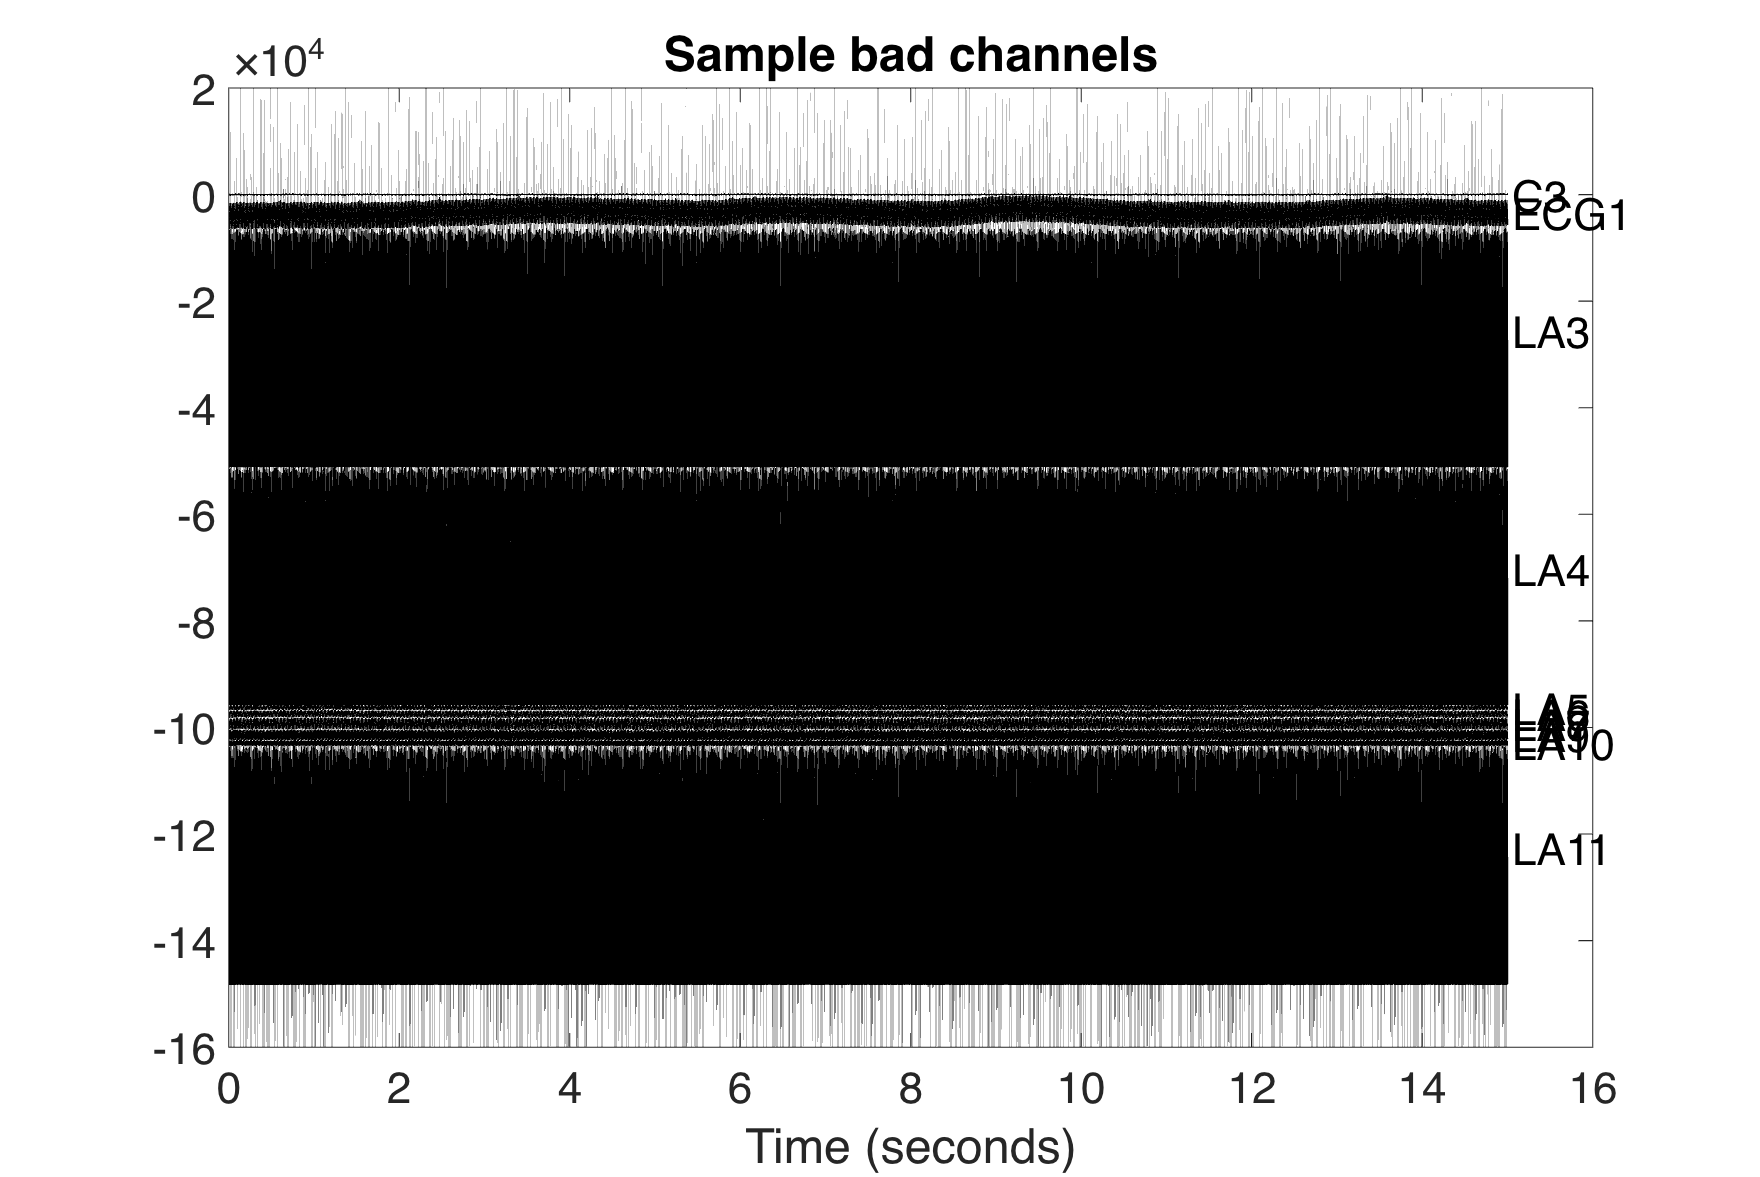

        show_values = values(:,~extra_cranial & ~bad);
        show_labels = labels(~extra_cranial & ~bad);

    case 'bipolar'
        show_values = values(:,~bad_ref & ~extra_ref);
        show_labels = labels(~bad_ref & ~extra_ref);
    case 'laplacian'
        show_values = values(:,~extra_cranial & ~bad);
        show_labels = labels(~extra_cranial & ~bad);
end

%for test
show_eeg(show_values,fs,show_labels,max_disp);
title('Sample Data after Bad Channel Removal')

### Pre-whiten

%% Pre-whiten data
whitened_values = pre_whiten(show_values);

% plot before/after whitening
show_eeg(whitened_values,fs,show_labels,max_disp);
title('Sample Data after Prewhitening')

### Final Plot

%% Plot all EEG
show_eeg(show_values,fs,show_labels);
title('Full Data')

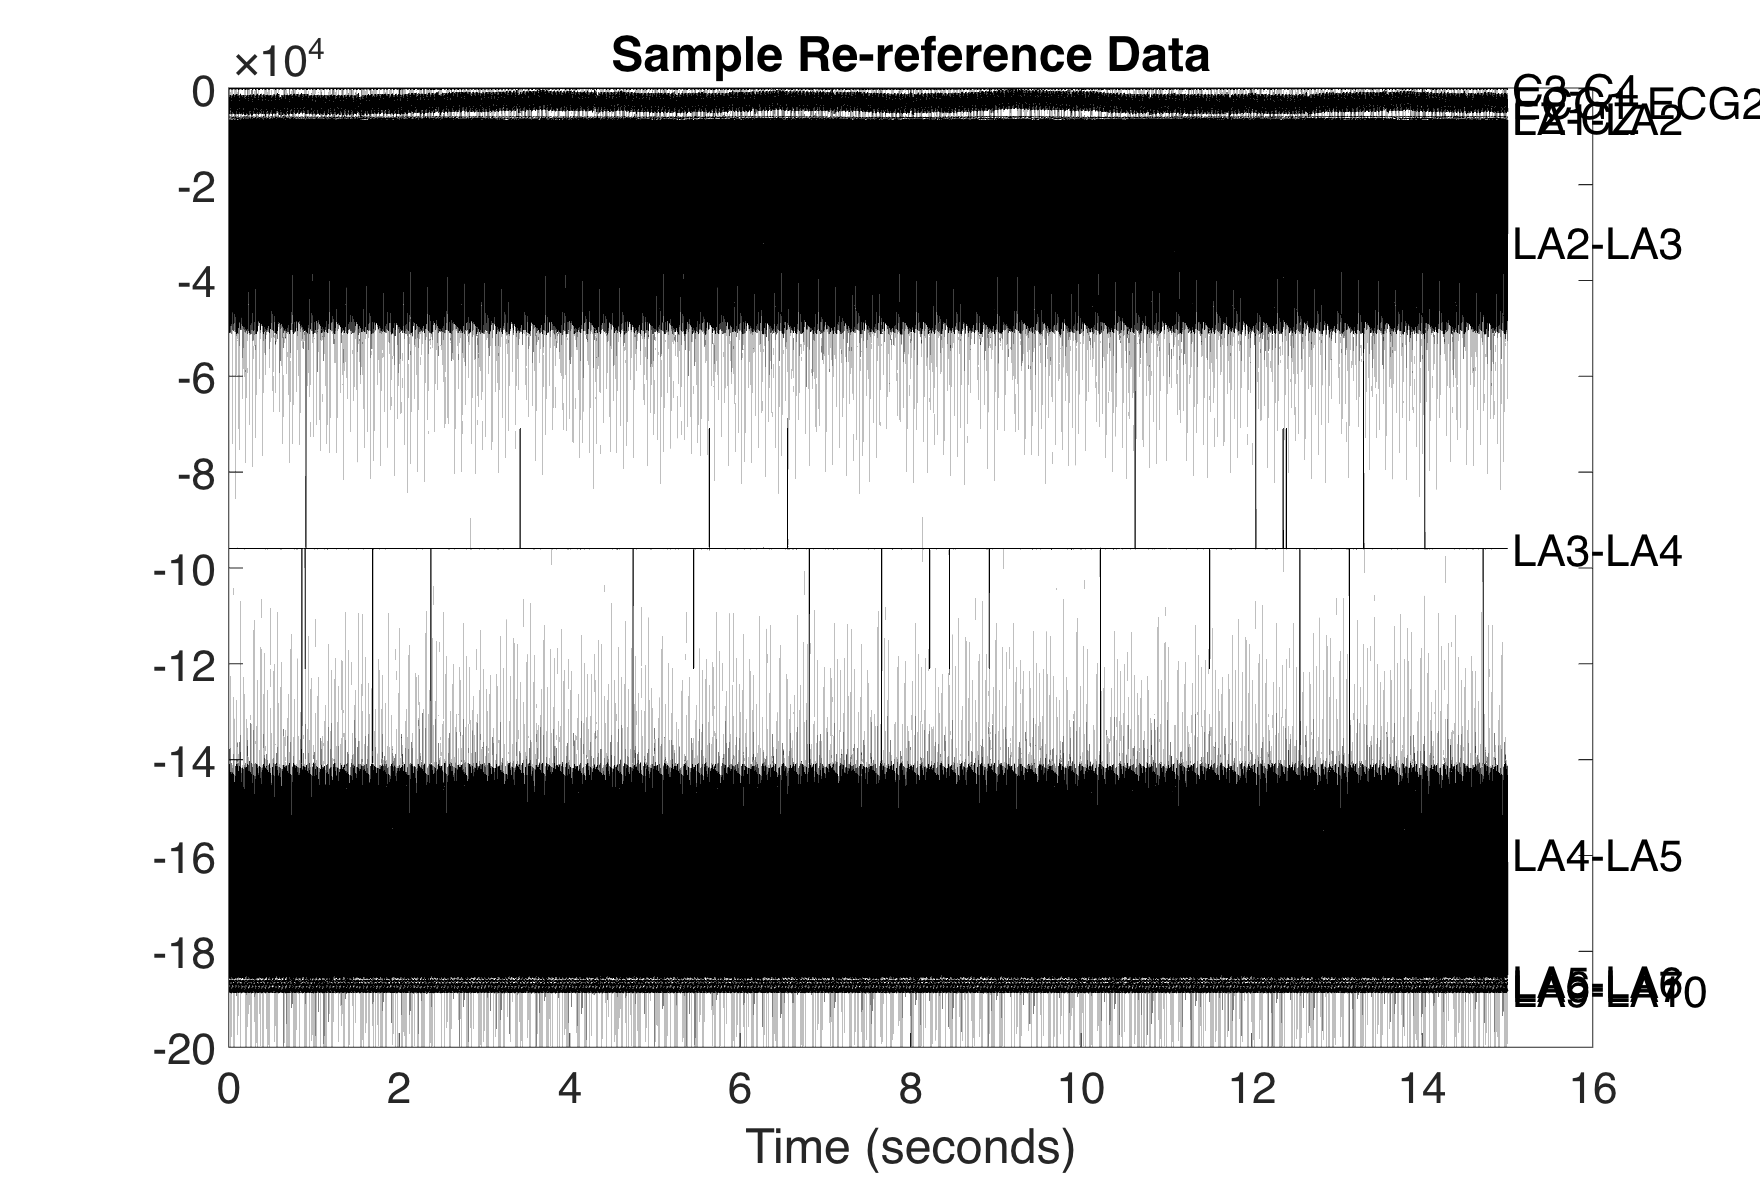

function [elec_names,elec_locs] = get_elec_names_locs_test(file_name)


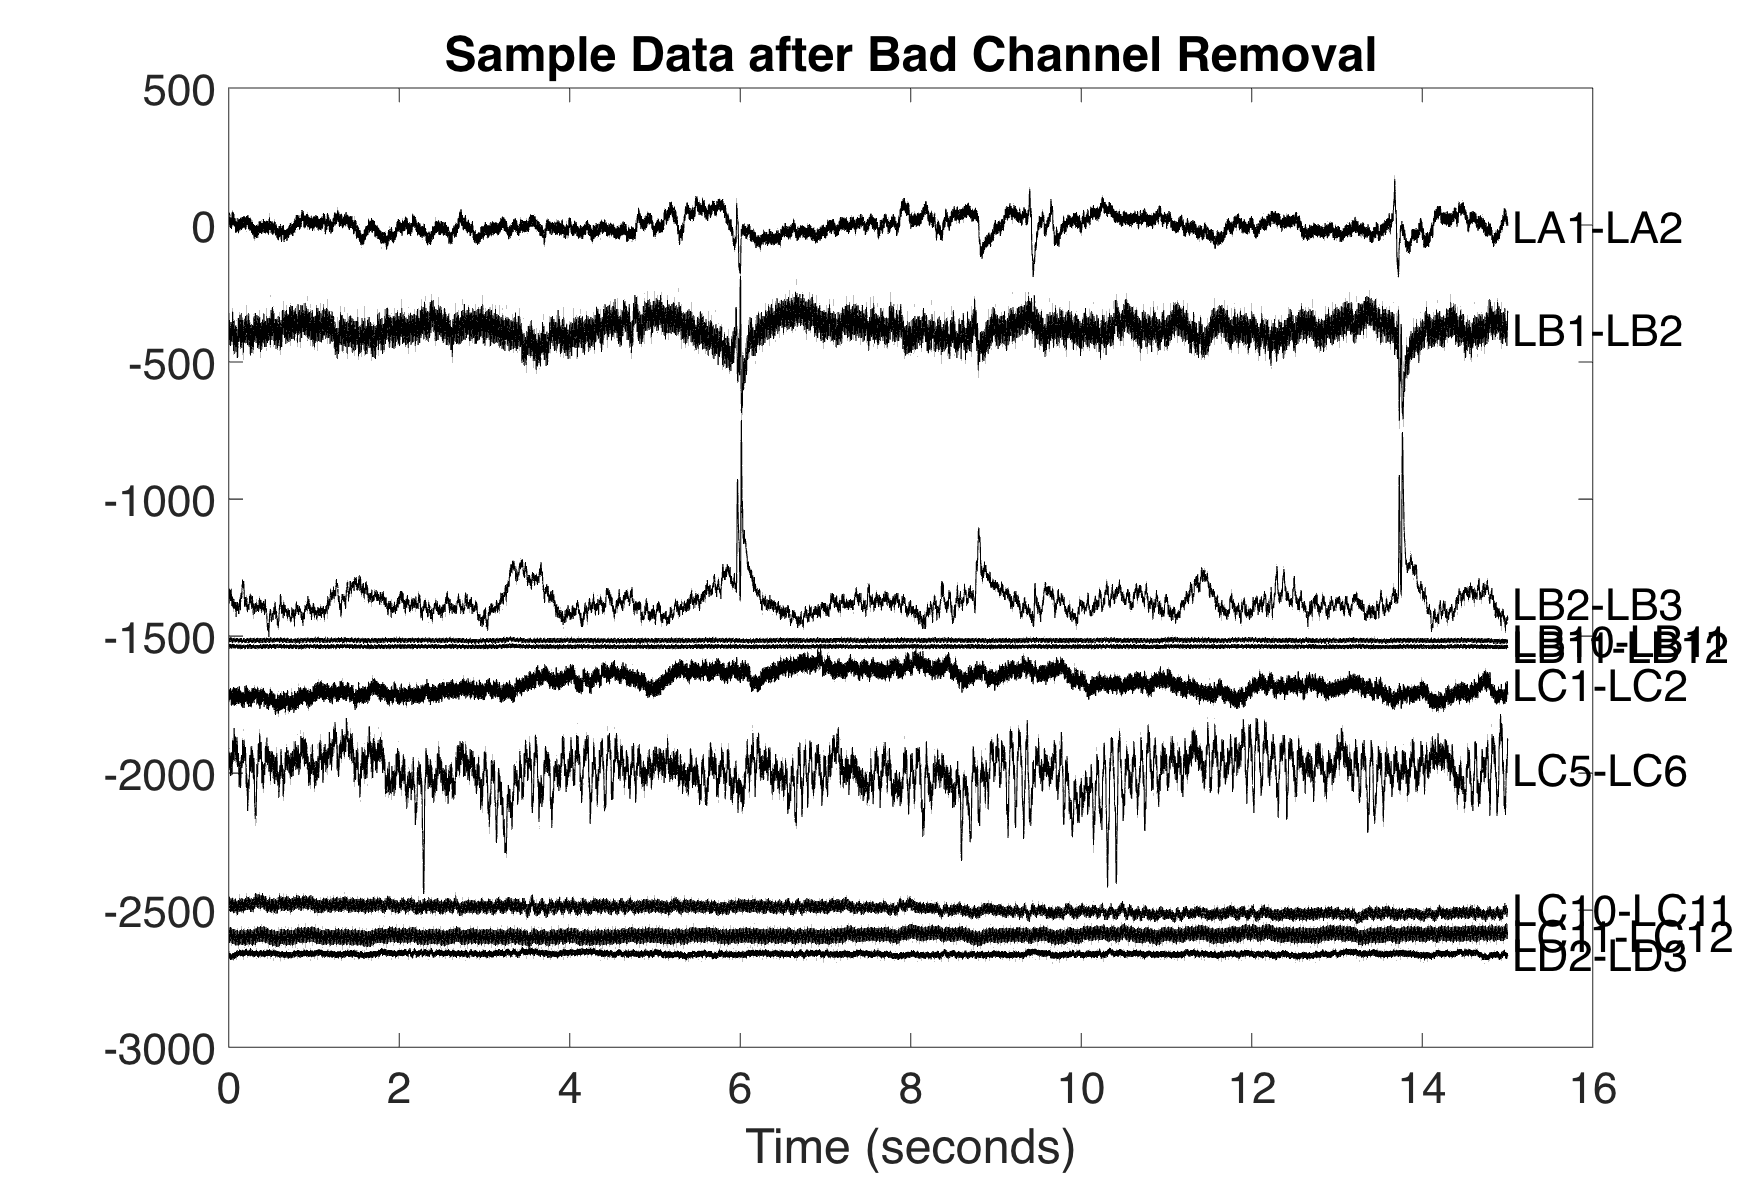

switch file_name
    
    case 'HUP212_phaseII'
        
        elec_locs = [...
            -21.9644	-3.96622	-19.17796222
-27.1833	-3.44744	-18.44270233
-32.3055	-3.15092	-17.79679578
-39.0948	-1.25976	-16.59815643
-44.0528	-0.489712	-15.40255739
-48.5465	0.768958	-15.40850885
-55.1978	0.807032	-15.15906381
-60.538	1.38142	-15.53825308
-65.6075	1.14542	-15.09903153
-70.4199	1.71736	-15.64636355
-75.3286	2.06474	-15.10412801
-80.0009	2.90778	-15.49598763
-26.7045	-15.0327	-18.58105175

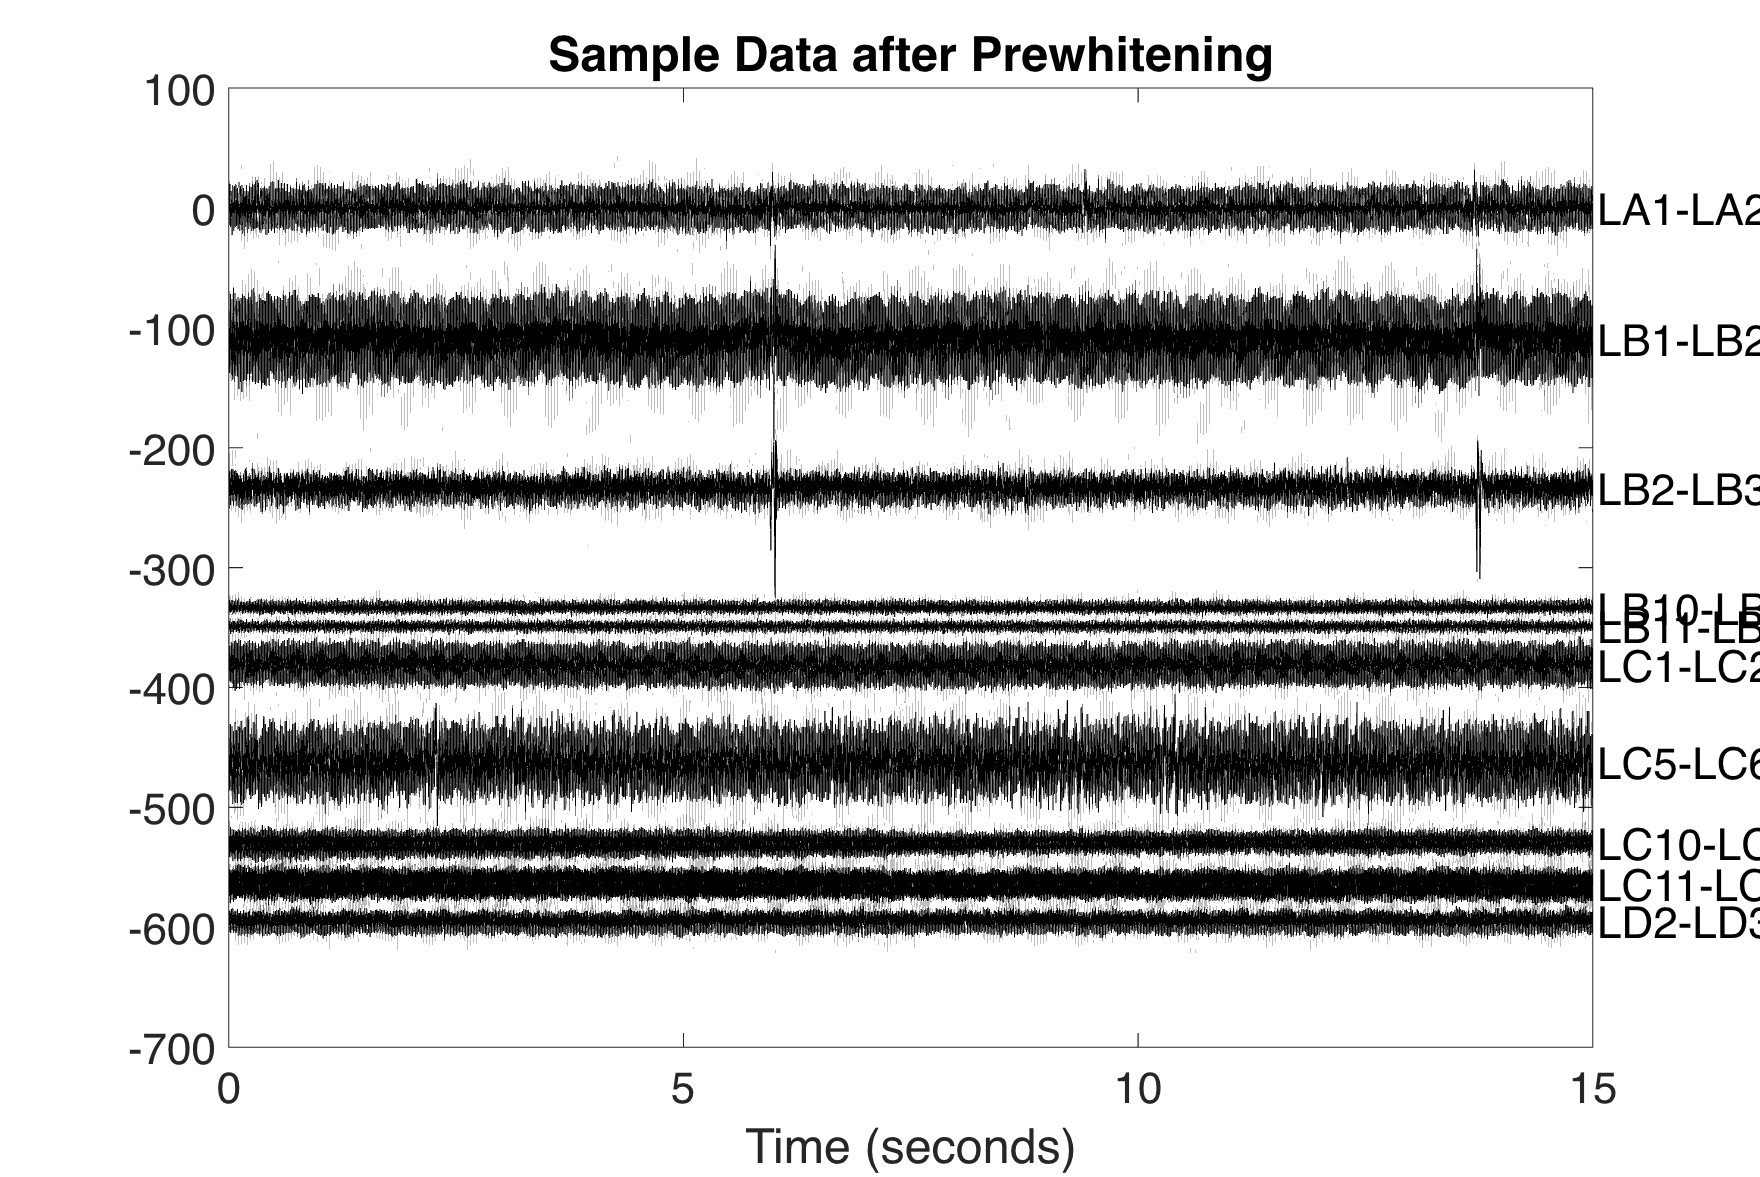

-32.4117	-14.823	-20.21053204
-37.9003	-14.0076	-20.06599719
-43.3946	-13.4336	-20.76403426
-50.3653	-13.2343	-22.36525626
-57.1174	-12.6516	-23.40728995
-62.1426	-11.9871	-22.80999385
-66.7956	-12.2104	-22.32842069
-71.2508	-12.4188	-22.25099011

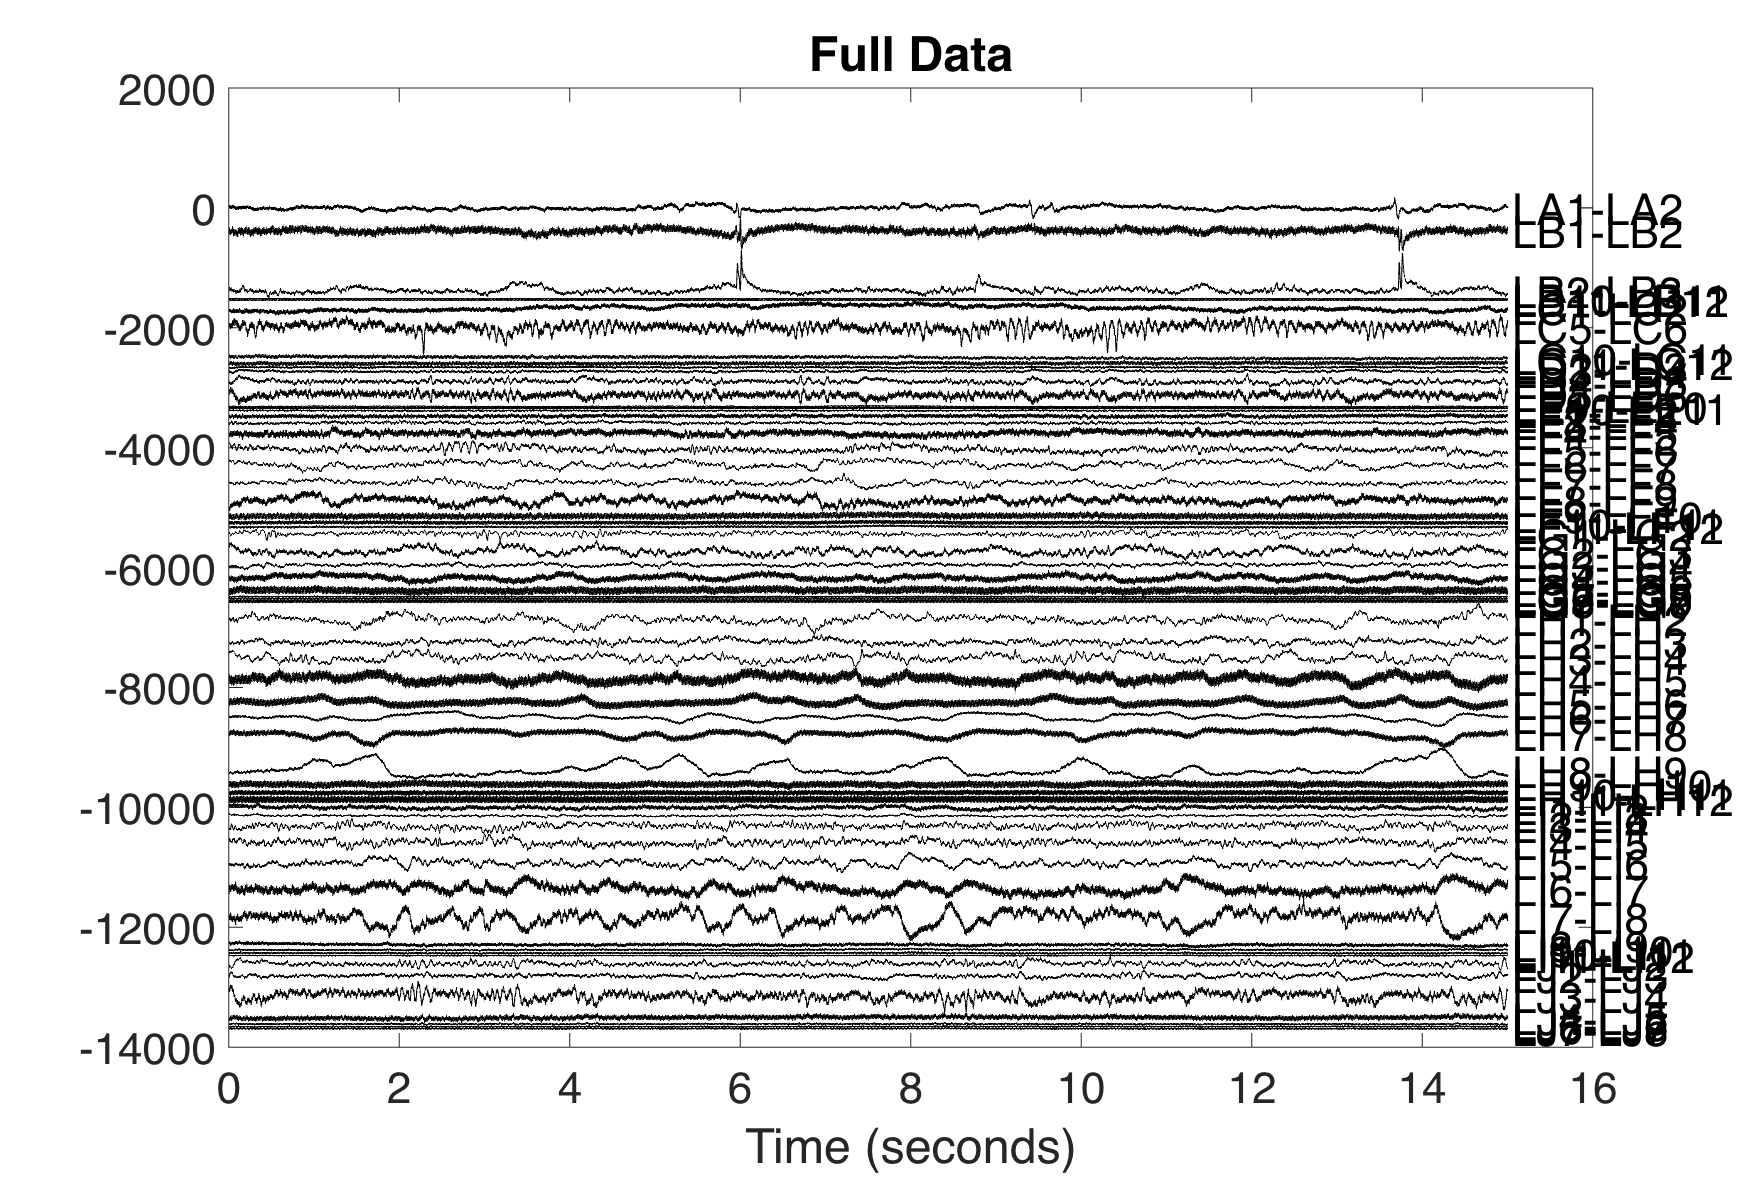

-76.2398	-12.2422	-22.56767281
-80.7358	-12.0199	-23.02477093
-85.206	-11.7818	-23.53768602
-27.0386	-34.357	-5.888741968
-30.9263	-37.2545	-5.460582141

-34.4973	-39.0266	-5.682187322
-37.9385	-40.2961	-5.119494705
-42.1857	-40.3808	-4.618095303
-47.8577	-38.1096	-2.421286522
-54.1769	-37.6359	-0.339474566
-59.2952	-41.999	0.171956003
-64.4853	-47.3658	0.325394978
-68.6765	-51.1339	1.894226787
-73.1036	-54.0419	3.081556424
-78.3748	-57.619	4.822050053
-30.7198	17.5605	2.573729422
-38.2437	18.5235	1.845022564
-44.0674	19.175	1.150472792
-51.043	19.4979	2.083736543
-56.5044	20.6868	3.542258649
-60.7093	21.4074	3.767050266
-64.7491	22.2595	2.709138339
-68.8753	23.987	1.996226842
-73.5157	25.2714	1.335912166
-78.007	26.3464	0.778783886
-82.3181	28.6037	-0.352905365
-84.8448	30.5121	-0.03018091
-39.7206	-1.1752	0.360960198
-48.3952	-0.677044	0.522601751
-53.8716	0.0200728	3.065538703
-58.6997	0.854095	4.506158307
-63.3329	2.0779	6.70260017
-67.4379	1.16552	7.298733845
-70.9826	0.471995	6.689633938
-75.6254	-0.342638	7.291688726
-80.6447	-0.352105	7.224435813
-85.4281	-0.288877	7.398567977
-89.8773	-0.740475	8.738613211
-95.2763	-0.680514	9.181493039
-27.5981	-10.9702	19.90410769
-32.5353	-13.4358	23.34843412
-36.6365	-15.0479	26.25333274
-40.8713	-17.4001	30.06830836
-43.3587	-18.9199	32.11575221
-47.2934	-22.1076	32.76880005
-53.5919	-23.3849	36.38317412
-58.8132	-23.9551	39.3732499
-62.8354	-25.4035	43.16435168
-65.9087	-26.9568	44.52706934
-69.4169	-28.1465	46.78588101
-73.6837	-29.9672	50.11515292
-35.871	27.5739	-5.418023327
-43.5716	27.5156	-2.141078501
-49.4345	28.9427	0.449780184
-53.5341	30.0246	1.533218578
-57.5827	31.4126	2.509476562
-61.6234	32.8536	4.445398469
-66.1864	34.8042	6.33075819
-69.6919	35.9725	7.106398113
-74.2392	36.8035	8.861932957
-78.9068	37.4961	10.63560042
-36.7133	32.1406	-18.55541135
-39.4306	32.0626	-12.77177319
-42.4288	32.2014	-5.674669878
-42.9744	34.1988	-1.054418893
-43.367	36.6898	2.909349162
-43.0377	40.3345	8.361377563
-42.2106	43.111	12.75353278
-41.9654	46.3626	17.67413951
-41.52	49.8596	21.95586691
-41.5494	51.8138	25.86749999
-42.1569	53.9664	29.91039282
-43.5972	56.4437	34.09331003
-9.79016	45.8851	19.91528878
-14.0826	42.8477	18.4617605
-18.1079	40.3809	20.26622146
-23.1047	39.4704	23.24626632
-27.4209	39.0189	26.39786438
-32.7418	39.0589	26.99158116
-39.9103	38.095	26.16693687
-45.9237	37.6553	27.59516753
-51.3357	37.2929	27.90705084
-56.5763	37.261	28.87865735
-62.6726	37.294	28.7408831
-68.2951	37.5528	28.82422239
-43.5093	20.8231	11.9598345
-49.1355	21.8657	14.30860324
-54.717	22.1062	14.72022558
-60.8376	21.0548	14.47748518
-65.1152	21.5716	12.46173217
-69.4259	22.3325	10.93033106
-73.7305	22.9895	11.13368293
-78.4911	23.537	10.25199761];

elec_names = {...
    'LA1';
'LA2';
'LA3';
'LA4';
'LA5';
'LA6';
'LA7';
'LA8';
'LA9';
'LA10';
'LA11';
'LA12';
'LB1';
'LB2';
'LB3';
'LB4';
'LB5';
'LB6';
'LB7';
'LB8';
'LB9';
'LB10';
'LB11';
'LB12';
'LC1';
'LC2';
'LC3';
'LC4';
'LC5';
'LC6';
'LC7';
'LC8';
'LC9';
'LC10';
'LC11';
'LC12';
'LD1';
'LD2';
'LD3';
'LD4';
'LD5';
'LD6';
'LD7';
'LD8';
'LD9';
'LD10';
'LD11';
'LD12';
'LE1';
'LE2';
'LE3';
'LE4';
'LE5';
'LE6';
'LE7';
'LE8';
'LE9';
'LE10';
'LE11';
'LE12';
'LF1';
'LF2';
'LF3';
'LF4';
'LF5';
'LF6';
'LF7';
'LF8';
'LF9';
'LF10';
'LF11';
'LF12';
'LG1';
'LG2';
'LG3';
'LG4';
'LG5';
'LG6';
'LG7';
'LG8';
'LG9';
'LG10';
'LH1';
'LH2';
'LH3';
'LH4';
'LH5';
'LH6';
'LH7';
'LH8';
'LH9';
'LH10';
'LH11';
'LH12';
'LI1';
'LI2';
'LI3';
'LI4';
'LI5';
'LI6';
'LI7';
'LI8';
'LI9';
'LI10';
'LI11';
'LI12';
'LJ1';
'LJ2';
'LJ3';
'LJ4';
'LJ5';
'LJ6';
'LJ7';
'LJ8'};

end
end